%Transfer Learning workflow

%Preparing Training Data: Labelling "C:\Users\isaac\Documents\MATLAB
path = "FinalProjectBagOfWords\images\FinalProjectSpectrograms\PAD_ROIS";
%load (path);
%rois = imageDatastore(path ,'IncludeSubfolders',true);
%roiNames = rois.Labels;

%Split into training and testing
% [birdTrain,birdTest] = splitEachLabel(flwrds,0.6);
% [birdTrain,birdTest] = splitEachLabel(flwrds,0.8,'randomized');


birdROIs = imageDatastore(path,'IncludeSubfolders',true,'LabelSource','foldernames');
birdNames = birdROIs.Labels;
numBirdTypes = numel(categories(birdROIs.Labels));

I = readimage(birdROIs, 1);
[roiRows, roiCols, dim] = size(I);
roiRows = round(roiRows * 0.25);
roiCols = round(roiCols * 0.25);

%Display images in datastore
% figure(1);
% roisT = countEachLabel(birdROIs);
% numOfROIs = sum(roisT.Count);
% idx = randperm(numOfROIs,20);
% for i = 1:20
%     subplot(4,5,i); 
%     I = readimage(birdROIs, idx(i));
%     imshow(I);
% end

%Load Network
net = resnet18;
layers = net.Layers;
inlayer = net.Layers(1);
insz = inlayer.InputSize;
% analyzeNetwork(net);

%Modify Neural Network Layers
% resnet18
lgraph = layerGraph(net);

newFCLayer = fullyConnectedLayer(numBirdTypes,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

%googlenet
% lgraph = layerGraph(net);
% 
% newFCLayer = fullyConnectedLayer(numBirdTypes,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
% lgraph = replaceLayer(lgraph,'loss3-classifier',newFCLayer);
% 
% newClassLayer = classificationLayer('Name','new_classoutput');
% lgraph = replaceLayer(lgraph,'output',newClassLayer);

%alexNet
% layers(end-2) = fullyConnectedLayer(numBirdTypes);
% layers(end) = classificationLayer;

%Training, Test Split
[birdTrain,birdTest] = splitEachLabel(birdROIs,30,10,'randomized');
roisTrainTable = countEachLabel(birdTrain);
numOfTrainROI = sum(roisTrainTable.Count);
roisTestTable = countEachLabel(birdTest);
numOfTestROI = sum(roisTestTable.Count);

%Augmented Images for PreEstablished Networks(googlenet, alexnet, resnet18)
augBirdTest = augmentedImageDatastore([insz(1),insz(2)],birdTest);
augBirdTrain = augmentedImageDatastore([insz(1),insz(2)],birdTrain);

%Augmented Images for CustomNet
% augBirdTest = augmentedImageDatastore([roiRows, roiCols],birdTest);
% augBirdTrain = augmentedImageDatastore([roiRows, roiCols],birdTrain);
%augROIs = partitionByIndex(augBirdROIs,[1:3251]);

%Custom Net
% layers = [imageInputLayer(inputResolution);
%           convolution2dLayer(3,32,'Stride',1);
%           batchNormalizationLayer(); 
%           reluLayer('Name','ReLu');
%           maxPooling2dLayer(1,'Stride',2);
%           convolution2dLayer(3,64,'Stride',2);
%           batchNormalizationLayer(); 
%           reluLayer();
%           maxPooling2dLayer(2,'Stride',2,'Name','pool');
%           dropoutLayer(0.5);
%           fullyConnectedLayer(numClasses, 'Name', 'FC'); 
%           softmaxLayer();
%           classificationLayer()];
% 
 options = trainingOptions('sgdm',... 
'MiniBatchSize', 10, ...
'MaxEpochs', 30, ... 
'LearnRateSchedule', 'piecewise', ...
'InitialLearnRate', 0.001, ...
'Shuffle',"once",...
'LearnRateDropPeriod', 5, ...
'LearnRateDropFactor', 0.2, ...
'L2Regularization', 0.0005, ...
'Momentum', 0.9, ...
'Verbose', false, ...
'VerboseFrequency', 10, ...
'ValidationFrequency', 20, ...
'ValidationData', augBirdTest, ...
'ValidationPatience',7, ...
"Plots","training-progress");



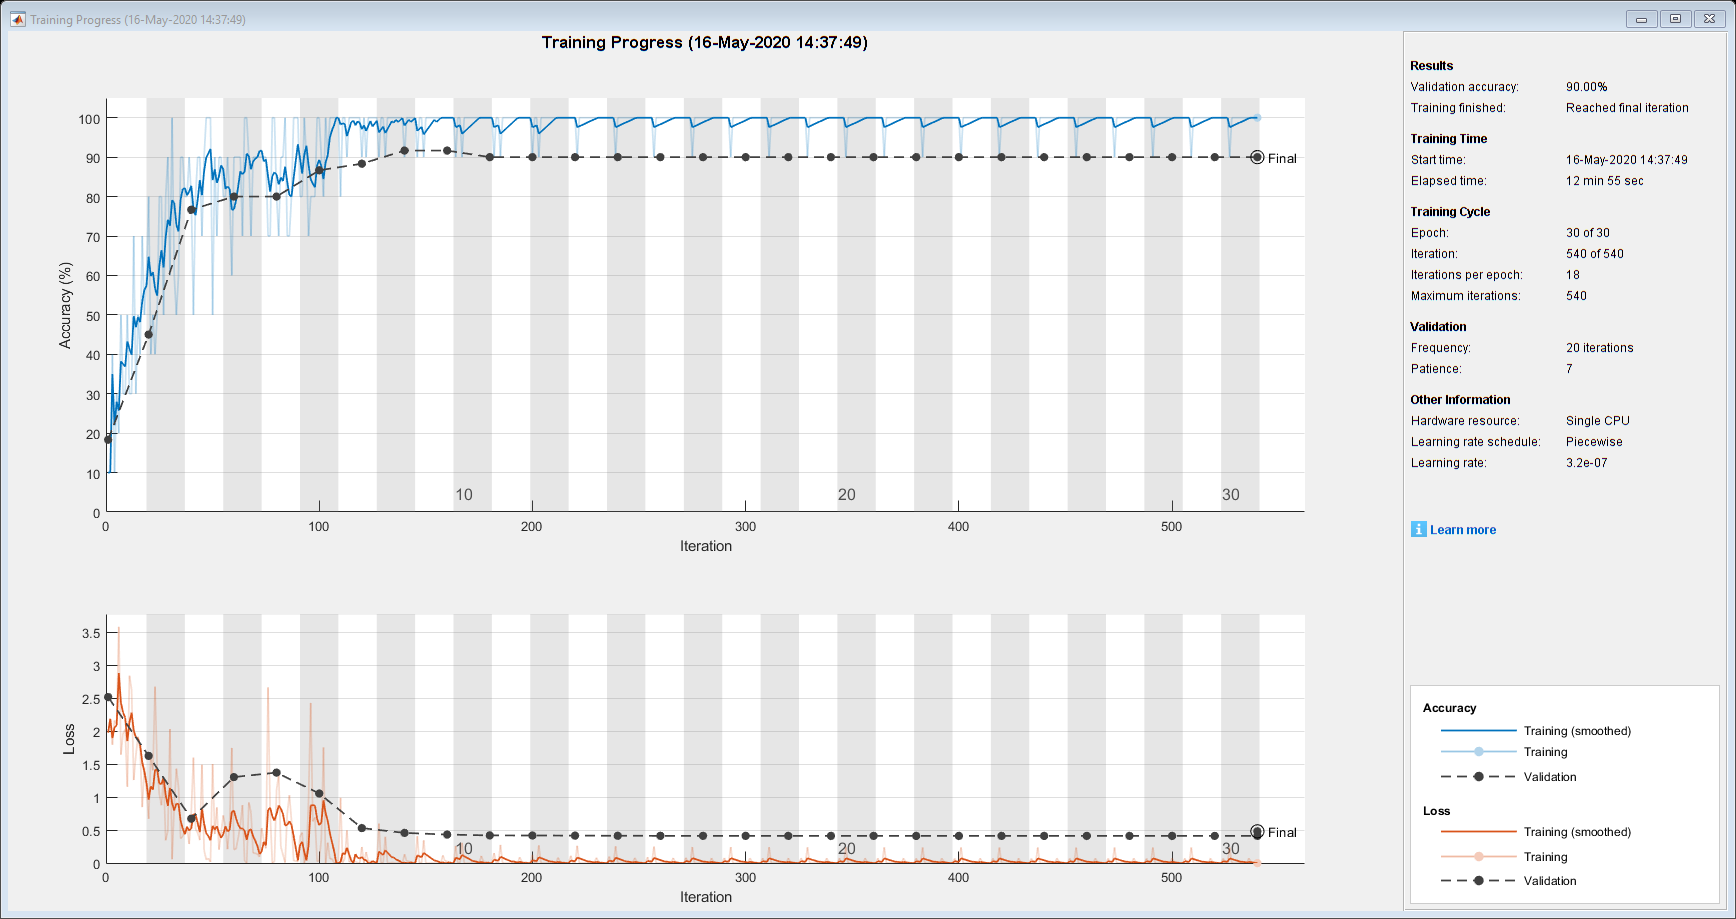

%Train Network if need be (CustomNet)
%[birdNet,info] = trainNetwork(birdTrain, layers, options);
[birdNet,info] = trainNetwork(augBirdTrain, lgraph, options);

%Use activations
analyzeNetwork(net);
layer = 'res2a';
featuresTrain = activations(birdNet,augBirdTrain,layer,'OutputAs','rows');
featuresTest = activations(birdNet,augBirdTest,layer,'OutputAs','rows');
featuresTrain = squeeze(featuresTrain);
% featuresTrain = featuresTrain.';
featuresTest = squeeze(featuresTest);
% featuresTest = featuresTest.';

% layer = 'pool';
% featuresTrain = activations(net,augBirdTrain,layer);
% featuresTest = activations(net,augBirdTest,layer);
% % 
% featuresTrain = squeeze(mean(featuresTrain,[1 2]))';
% featuresTest = squeeze(mean(featuresTest,[1 2]))';

whos featuresTrain;

  Name                 Size                    Bytes  Class     Attributes

  featuresTrain      180x200704            144506880  single              



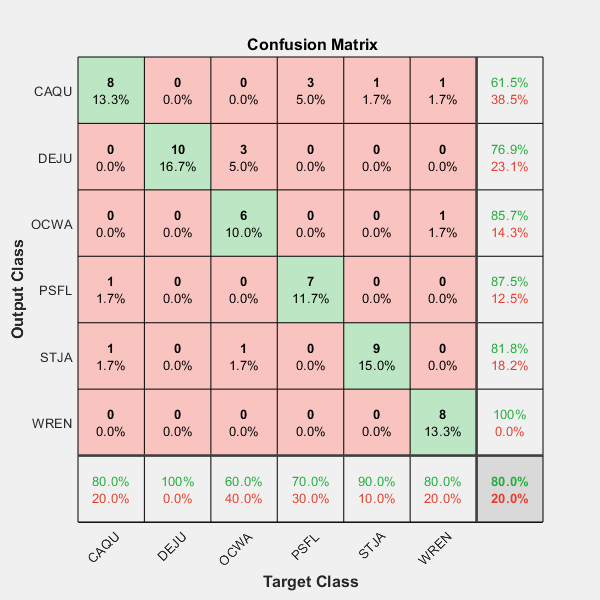


%Create a network by modifying AlexNet

% layers(end-2) = fullyConnectedLayer(numBirdTypes);
% layers(end) = classificationLayer;
% 
% %Set training algorithm options
% 
% options = trainingOptions('sgdm','InitialLearnRate', 0.001);

YTrain = birdTrain.Labels;
YTest = birdTest.Labels;
%Fit Image Classifier
classifier = fitcecoc(featuresTrain,YTrain);
YPred = predict(classifier,featuresTest);

figure
%confusionchart(YTest,YPred);
cm = plotconfusion(YTest, YPred);

[cm, order] = confusionmat(YTest, YPred);
confMat = cm;
%fscore = zeros(size(confMat,1));
for i =1:size(confMat,1)
    recall =confMat(i,i)/sum(confMat(i,:));
    precision=confMat(i,i)/sum(confMat(:,i));
    f_score(i) = 2*recall*precision/(precision+recall);
end

avgfscore = sum(f_score)/numel(f_score);
disp('f_scores:');

f_scores:


disp(num2str(f_score));

0.69565     0.86957     0.70588     0.77778     0.85714     0.88889


fprintf('Average f_score: %d', avgfscore);

Average f_score: 7.991515e-01

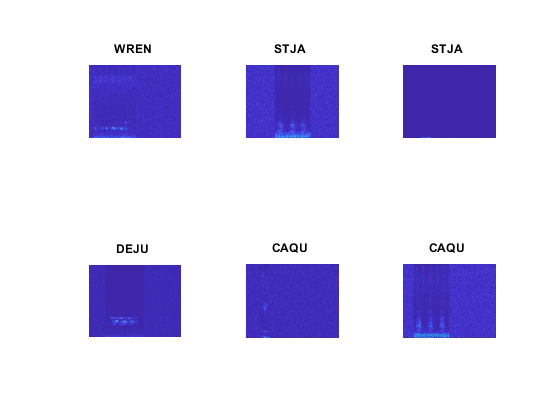



%Display images with predicted labels
idx = randperm(numOfTestROI,6);
figure
for i = 1:numel(idx)
    subplot(2,3,i)
    I = readimage(birdTest,idx(i));
    label = YPred(idx(i));
    imshow(I)
    title(char(label))
end


accuracy = mean(YPred == YTest);

% numCorrect = nnz(testPreds == birdTestTypes);
% fracCorrect = numCorrect/numel(testPreds);
% figure(2);
% confusionchart(birdTestTypes,testPreds);